## Data Import & Cleaning

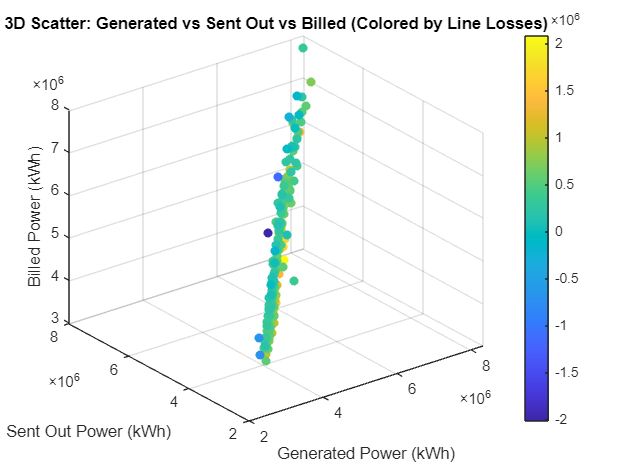

% Import data from the Excel file
TPL = importfile("ALL_Data.xlsx");

% Remove unnecessary or redundant variables to focus on key features
TPL1 = removevars(TPL, ["MONTH", "PARASITIC", "LINE", "TOTAL", ...
    "PARASITIC_PERCENTAGE", "LINE_PERCENTAGE", "TOTAL_PERCENTAGE", ...
    "AVERAGE_PARASITIC_PAST_12_MONTHS", "AVERAGE_LINE_PAST_12_MONTHS", ...
    "AVERAGE_TOTAL_PAST_12_MONTHS","TARGET_PERCENTAGE", ...
    "FUEL_USE", "DIESEL_GEN","FUEL_EFFICIENCY_DIESEL", ...
    "FUEL_EFFICIENCY_WITH_RE"]);

% Assign cleaned data for further processing
TPL_clean = TPL1;  % Ensure no NaN values exist after this step (manual check)

%% 3D Scatter Plot of Key Features
figure;
scatter3(TPL_clean.GENERATED, TPL_clean.SENT_OUT, TPL_clean.BILLED, [], TPL.LINE, 'filled');
xlabel('Generated Power (kWh)');
ylabel('Sent Out Power (kWh)');
zlabel('Billed Power (kWh)');
colorbar;
title('3D Scatter: Generated vs Sent Out vs Billed (Colored by Line Losses)');

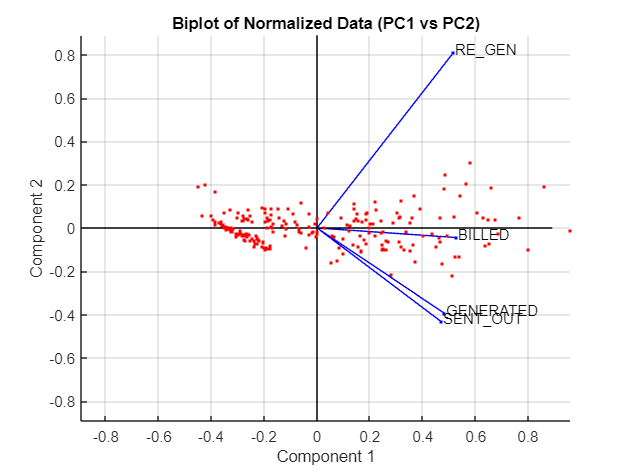


%% Grouped 2D Scatter Plot by Year
years = year(TPL.MONTH);  % Extract year from datetime
figure;
gscatter(TPL_clean.BILLED, TPL_clean.SENT_OUT, years, parula(numel(unique(years))));
xlabel('Billed Power (kWh)');
ylabel('Sent Out Power (kWh)');
legend('Location', 'eastoutside', 'FontSize', 8);
title('Billed vs Sent Out Power Grouped by Year');

%% Principal Component Analysis (PCA)

% Unnormalized PCA
[coeff_raw, score_raw, latent_raw, tsquared_raw, explained_raw, mu_raw] = pca(TPL_clean{:,:});

% Normalized PCA (scale features to range [0,1])
X_norm = normalize(TPL_clean{:,:}, 'range');
[coeff_norm, score_norm, latent_norm, tsquared_norm, explained_norm, mu_norm] = pca(X_norm);

% Biplot (Normalized Data)
biplot(coeff_norm(:,1:2), 'Scores', score_norm(:,1:2), 'VarLabels', TPL_clean.Properties.VariableNames);
title('Biplot of Normalized Data (PC1 vs PC2)');

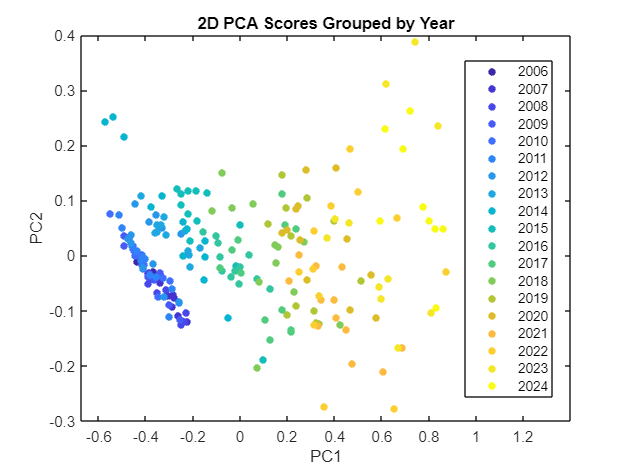


%% PCA Grouped by Year (2D)
groups = year(TPL.MONTH);
[unique_groups, ~, group_idx] = unique(groups);
colors = parula(numel(unique_groups));

figure;
gscatter(score_norm(:,1), score_norm(:,2), groups, colors);
xlabel('PC1');
ylabel('PC2');
title('2D PCA Scores Grouped by Year');

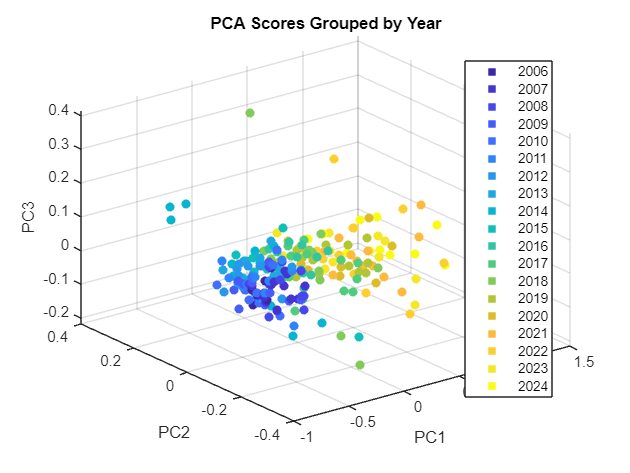


%% PCA Grouped by Year (3D)
point_colors = colors(group_idx, :);

figure;
scatter3(score_norm(:,1), score_norm(:,2), score_norm(:,3), [], point_colors, 'filled');
xlabel('PC1'); ylabel('PC2'); zlabel('PC3');
title('PCA Scores Grouped by Year');

% Legend for grouped scatter
hold on;
h = arrayfun(@(x) plot3(NaN, NaN, NaN, 's', ...
    'MarkerFaceColor', colors(x,:), 'MarkerEdgeColor', colors(x,:)), ...
    1:numel(unique_groups), 'UniformOutput', false);
hold off;
legend([h{:}], num2str(unique_groups), 'Location', 'best');

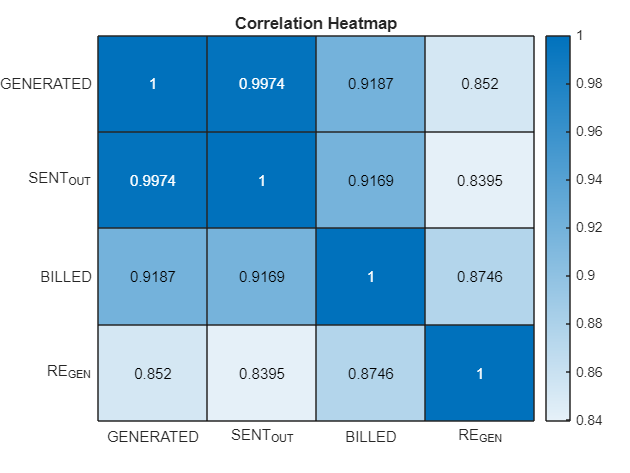


%% Correlation Heatmap
figure;
heatmap(corr(TPL_clean{:,:}), ...
    'XData', TPL_clean.Properties.VariableNames, ...
    'YData', TPL_clean.Properties.VariableNames);
title('Correlation Heatmap');

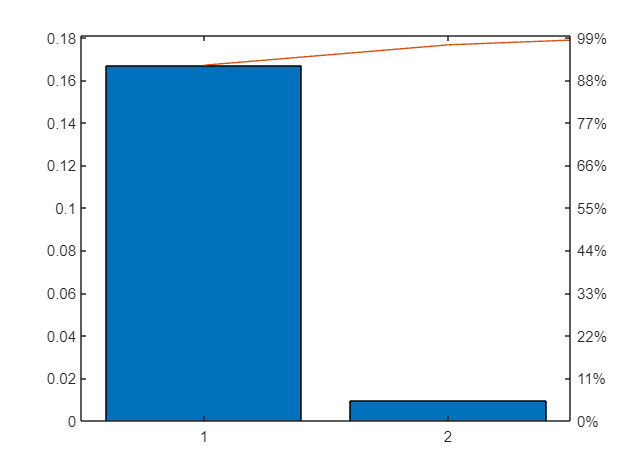


%% Intrinsic Dimensionality Visualization
figure;
pareto(latent_norm);  % Explained variance from PCA


% Dy-Dx Plot
figure(1)
P = score_norm(:,1:3);  % Top 3 PCs
OriginalDataDist = squareform(pdist(X_norm));
dydxplot(P, OriginalDataDist);  % Visualize manifold distances

%% Canonical Correlation Analysis (CCA)
D = X_norm;
K = 3;            % Output dimension
epochs = 20;      % Training iterations
dist = squareform(pdist(X_norm));
alpha0 = 0.5;
lambda0 = 5;

P = cca(D, K, epochs, [dist], [alpha0], [lambda0]);

iterating: 0 / 20 epochs
iterating: 1 / 20 epochs
iterating: 2 / 20 epochs
iterating: 3 / 20 epochs
iterating: 4 / 20 epochs
iterating: 5 / 20 epochs
iterating: 6 / 20 epochs
iterating: 7 / 20 epochs
iterating: 8 / 20 epochs
iterating: 9 / 20 epochs
iterating: 10 / 20 epochs
iterating: 11 / 20 epochs
iterating: 12 / 20 epochs
iterating: 13 / 20 epochs
iterating: 14 / 20 epochs
iterating: 15 / 20 epochs
iterating: 16 / 20 epochs
iterating: 17 / 20 epochs
iterating: 18 / 20 epochs
iterating: 19 / 20 epochs
iterating: 20 / 20 epochs
20 iterations, error 0.000180          


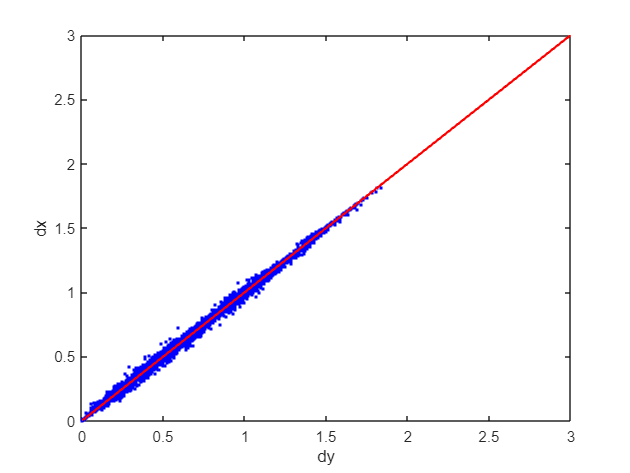


% Dy-Dx Plot on CCA results
figure(3)
dydxplot(P, squareform(pdist(X_norm)));

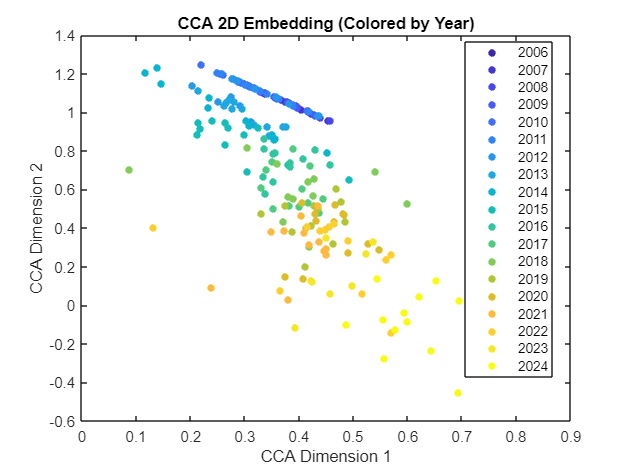


%% 2D CCA Embedding Grouped by Year
figure;
gscatter(P(:,1), P(:,2), year(TPL.MONTH), parula(numel(unique(year(TPL.MONTH)))));
xlabel('CCA Dimension 1');
ylabel('CCA Dimension 2');
title('CCA 2D Embedding (Colored by Year)');

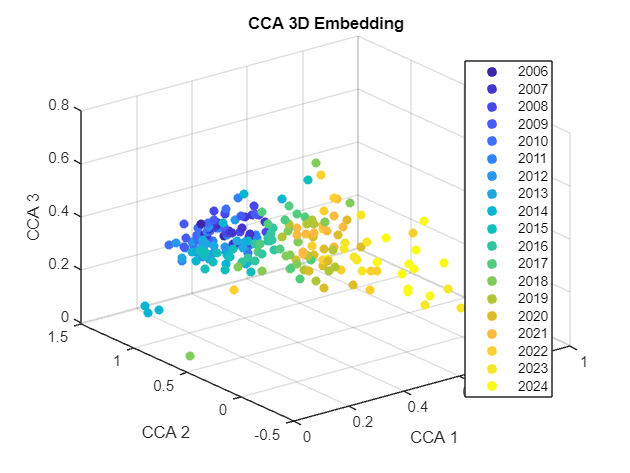


%% 3D CCA Embedding Grouped by Year
point_colors = colors(group_idx, :);

figure;
scatter3(P(:,1), P(:,2), P(:,3), 36, point_colors, 'filled');
xlabel('CCA 1'); ylabel('CCA 2'); zlabel('CCA 3');
title('CCA 3D Embedding');

% Legend entries
hold on;
h = arrayfun(@(x) plot3(NaN, NaN, NaN, 'o', ...
    'MarkerFaceColor', colors(x,:), ...
    'MarkerEdgeColor', colors(x,:), 'MarkerSize', 6), ...
    1:numel(unique_groups), 'UniformOutput', false);
hold off;
legend([h{:}], num2str(unique_groups), 'Location', 'best');

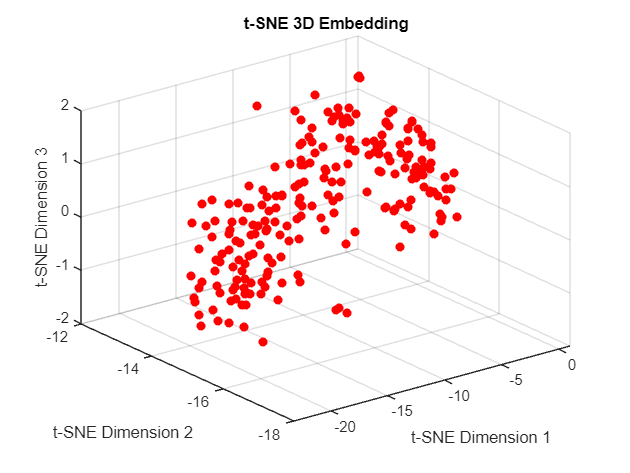


%% t-SNE Embedding
Y_tsne = tsne(TPL_clean{:,:}, 'NumDimensions', 3, 'Perplexity', 50);

% 3D t-SNE plot
figure;
scatter3(Y_tsne(:,1), Y_tsne(:,2), Y_tsne(:,3), 'r', 'filled');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
zlabel('t-SNE Dimension 3');
title('t-SNE 3D Embedding');

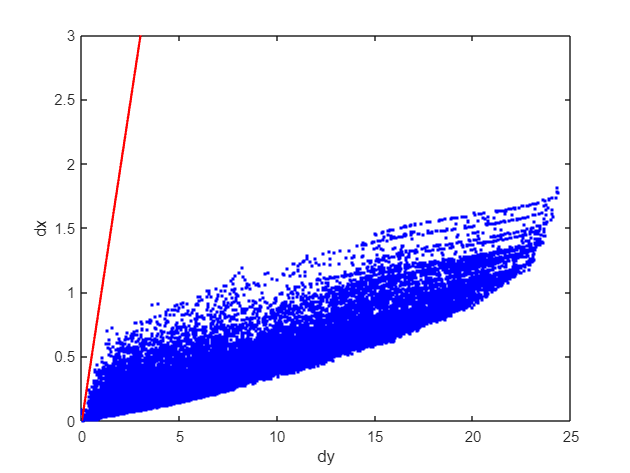


% 2D t-SNE with Grouping
figure;
gscatter(Y_tsne(:,1), Y_tsne(:,2), year(TPL.MONTH), parula(numel(unique(year(TPL.MONTH)))));
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
title('t-SNE 2D Embedding (Colored by Year)');

% Dy-Dx Plot
O = Y_tsne(:,1:3);
OriginalDataDist = squareform(pdist(X_norm));
dydxplot(O, OriginalDataDist);

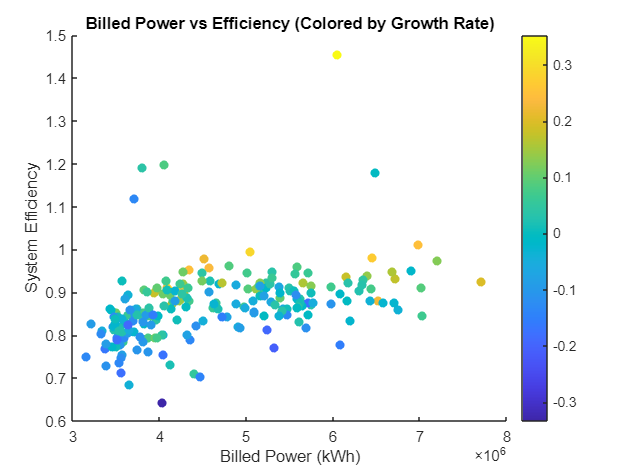


%% Feature Engineering

% 1. Lagged Billed Value
TPL_clean.BILLED_LAG1 = [NaN; TPL_clean.BILLED(1:end-1)];

% 2. 12-Month Rolling Average
TPL_clean.BILLED_12M_AVG = movmean(TPL_clean.BILLED, [11 0]);

% 3. System Efficiency (Billed / Generated)
TPL_clean.SYSTEM_EFFICIENCY = TPL_clean.BILLED ./ TPL_clean.GENERATED;

% 4. Demand Growth Rate
TPL_clean.DEMAND_GROWTH_RATE = ...
    (TPL_clean.BILLED - TPL_clean.BILLED_LAG1) ./ TPL_clean.BILLED_LAG1;

% 5. Seasonal Feature Encoding (Sin/Cos)
numeric_month = month(TPL.MONTH);
TPL_clean.SEASONALITY_SIN = sin(2 * pi * numeric_month / 12);
TPL_clean.SEASONALITY_COS = cos(2 * pi * numeric_month / 12);

% Optional: Remove rows with NaNs introduced by lagging
% TPL_clean = rmmissing(TPL_clean);

%% Feature Exploration Plots

% Billed vs System Efficiency (colored by Growth Rate)
figure;
scatter(TPL_clean.BILLED, TPL_clean.SYSTEM_EFFICIENCY, [], ...
    TPL_clean.DEMAND_GROWTH_RATE, 'filled');
colorbar;
xlabel('Billed Power (kWh)');
ylabel('System Efficiency');
title('Billed Power vs Efficiency (Colored by Growth Rate)');

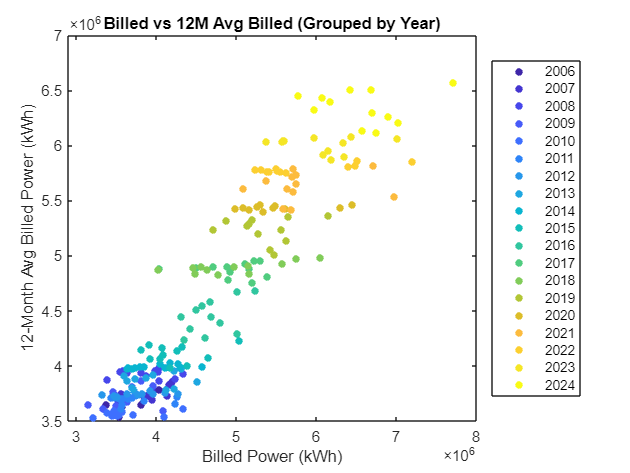


% Billed vs 12-Month Average (Grouped by Year)
years_clean = year(TPL.MONTH);
figure;
gscatter(TPL_clean.BILLED, TPL_clean.BILLED_12M_AVG, ...
    years_clean, parula(numel(unique(years_clean))));
xlabel('Billed Power (kWh)');
ylabel('12-Month Avg Billed Power (kWh)');
legend('Location', 'eastoutside');
title('Billed vs 12M Avg Billed (Grouped by Year)');